clc
clear all; close all;
cd("C:\Users\athul.p\Documents\GitHub\Power_System_Dynamics\HW6")
% cd("C:\Users\athul.p\Documents\GitHub\PowerSystemDynamic")
% Initializing Kundur 2 area system and importing data
n_bus = 11;
bus_data = importdata('ieee11bus.txt').data;
% bus_data = importdata('ieee11bus_allPV.txt').data;
branch_data = importdata('ieee11branch.txt').data;
   
% Ybus formation
t = 0; % 0 for without tap, 1 for with tap
Y = y_bus_calc(n_bus,bus_data,branch_data,t);

% Scheduled power calculation
base_MVA = 100;
P_inj = (bus_data(:,8) - bus_data(:,6)) / base_MVA;
Q_inj = (bus_data(:,9) - bus_data(:,7)) / base_MVA;

% Finding bus types
pv_i = find(bus_data(:,3) == 2);
pq_i = find(bus_data(:,3) == 0);
n_pv = length(pv_i);
n_pq = length(pq_i);

% Initializing Voltage magnitude and angles
V = bus_data(:,11);
V(find(V(:)==0)) = 1;
T = zeros(n_bus,1);

% Newton Raphson Method
[V1_data,T1_data,T1] = NR(bus_data,V,T,P_inj,Q_inj,n_bus,Y,n_pq,pq_i);
% V = V1_data(:,end)
% T = T1_data(:,end)

% Fast Decoupled Mehod
%[V2_data,T2_data,T2] = FD(bus_data,V,T,P_inj,Q_inj,n_bus,Y,n_pq,pq_i);

% P,Q calculation after convergence
[P,Q] = PQ_calc(V1_data(:,size(V1_data,2)),T1_data(:,size(T1_data,2)),Y);
V = V1_data(:,size(V1_data,2));
T = T1_data(:,size(T1_data,2));
% [P,Q] = PQ_calc(V,T,Y)

% plotting convergence curves
% mplot([1:size(V1_data,2)],T1,[1:size(V1_data,2)],T1)

bus_data = importdata('ieee11bus_ynet.txt').data;
branch_data = importdata('ieee11branch_ynet.txt').data;
t = 0; % 0 for without tap, 1 for with tap
n_bus = 14;
Y = y_bus_calc(n_bus,bus_data,branch_data,t);

% calculating Ygen matrix

Y_gen = Y_gen_calc(Y)

Y_gen =    3.1519 -12.6973i   1.5578 + 7.2405i   1.0648 + 1.5522i   1.5415 + 2.1172i
   1.5578 + 7.2405i   1.2990 -10.9915i   0.7550 + 0.9705i   1.0880 + 1.3202i
   1.0648 + 1.5522i   0.7550 + 0.9705i   1.5317 - 8.3645i   1.8025 + 3.9505i
   1.5415 + 2.1172i   1.0880 + 1.3202i   1.8025 + 3.9505i   2.6612 -10.2282i



P_gen = P(2:4);
Q_gen = Q(2:4);
V(12:14) = V(2:4);
T(12:14) = T(2:4);

% calculating Igen
I_gen = (P_gen - i*Q_gen)./(V(12:14).*exp(-i*T(12:14)));

X_gen = (((0.3+0.55)/2)*base_MVA/900);

% calculating Egen
E = (V(12:14).*exp(i*T(12:14))) + (i*X_gen.*I_gen);
[Theta, E_g] = cart2pol(real(E),imag(E))

Theta =     0.1541
    0.1178
   -0.0440


E_g =     1.0844
    1.1270
    1.0748


E_g = [V(1); E_g]

E_g =     1.0300
    1.0844
    1.1270
    1.0748


Theta = [T(1); Theta]

Theta =          0
    0.1541
    0.1178
   -0.0440


## using fsolve

x0 = [0.5 1.2 0.5 1.2 0.5 1.2]

fun = @(x)paramfun(x, P_gen, Y_gen, E_g); x = fsolve(fun,x0)

## using vpasolve

t = sym('t', [1 3]);
w = sym('w', [1 3]);

F = type3(t, w, P_gen, Y_gen, E_g);
solVal0 = [0, 0, 0, 1, 1, 1]

solVal0 =      0     0     0     1     1     1


vars = [t, w];

sol = vpasolve(F == 0, vars, solVal0)

sol = struct with fields:
    t1: 0.15413780561398847267985638529707
    t2: 0.1178366462094189064397647195303
    t3: -0.043987884005915990696011754641505
    w1: 1.0
    w2: 1.0
    w3: 1.0



% solVal = [sol.t, sol.w]
trans_init = [];
% making Jacobian
for i = 1:length(vars)
    % for j = 1:3
        % J(i,j) = diff(F(i),t(j));
        % J(i,j+3) = diff(F(i),w(j));
    % end
    sol_val{i} = sol.(char(vars(i)));
    trans_init = [trans_init double(sol.(char(vars(i))))];
end
J = jacobian(F, vars);
% vpa(J, 3)

% substituting solution
J_val = subs(J, vars, sol_val)

$$J\_val = \left(\begin{array}{cccccc} 0 & 0 & 0 & 120\,\pi & 0 & 0\\ 0 & 0 & 0 & 0 & 120\,\pi & 0\\ 0 & 0 & 0 & 0 & 0 & 120\,\pi \\ -0.086626996116801148655277056914762 & 0.0098453481989559730664870346455522 & 0.010761209391209686856971711258813 & -\frac{10}{39} & 0 & 0\\ 0.01096616342526626004594748342611 & -0.065082898843310010665081235012974 & 0.039324883807621175452846768449917 & 0 & -\frac{200}{741} & 0\\ 0.015818702483321907308046491080599 & 0.045654864862407244644693521390181 & -0.083214269120939333849758059485878 & 0 & 0 & -\frac{200}{741} \end{array}\right)$$

J_val = double(J_val);

% eigen value and vectors
[r_ev, eig_val] = eig(J_val);
l_ev = inv(r_ev);

% participation factor
norm_p = []; 
for i = 1: length(vars)
    p_mat = r_ev(:,i)*l_ev(i,:);
    diag_vec = abs(diag(p_mat));
    norm_p = [norm_p diag_vec./max(diag_vec)];
end

% calculating mode frequency
eigen_frequency_mode= abs(imag(diag(eig_val)))/2/pi;

## Transient Stability

% Ybus
Y_pre = Y;
Y_fault = y_fault_update();
Y_post = y_post_update();

% generating fault on system equations
Y_gen_fault = Y_gen_calc(Y_fault);
F_fault = type3(t, w, P_gen, Y_gen_fault, E_g);

% generating post fault system equations
Y_gen_post = Y_gen_calc(Y_post);
% Y_gen_post = [
%     3.34818416211970 - 12.5097816042871i    1.69301629808215 + 7.35484140935891i    1.05061019016509 + 1.27989784816729i    1.51113287696272 + 1.73895013443404i;
%     1.69301629808215 + 7.35484140935891i    1.39160840514599 - 10.9218584241740i    0.735111802576862 + 0.793462894303177i    1.05335076132197 + 1.07477470896015i;
%     1.05061019016509 + 1.27989784816729i    0.735111802576862 + 0.793462894303177i    1.68186098239602 - 8.38475253826988i    2.01054710714309 + 3.91609536599460i;
%     1.51113287696272 + 1.73895013443403i    1.05335076132197 + 1.07477470896015i    2.01054710714309 + 3.91609536599460i    2.94915872700349 - 10.2836578984531i
% ];
F_post = type3(t, w, P_gen, Y_gen_post, E_g);

% t_k = [0.1541378056; 0.1178366462; -0.0439878840];
% w_k = [1.0; 1.0; 1.0];
t_k = trans_init(1:3)';
w_k = trans_init(4:6)';
time_data = [0];
t_data = t_k;
w_data = w_k;
% h = 0.02;
h = 1e-3

h = 1.0000e-03

ax =   Axes with properties:

             XLim: [0 35]
             YLim: [-0.1000 0.2500]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1551 0.7750 0.7699]
            Units: 'normalized'

  Show all properties


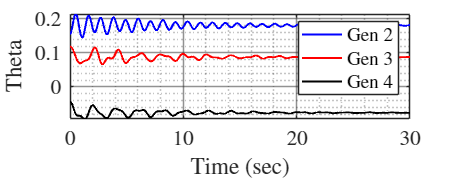


Tf = 0;
Tc = 0/60;
Ts = 30;
for time = 0:h:Tf-h
    F_val = double(subs(F, vars, [t_k ; w_k].'));
    t_kn = t_k + (F_val(1:3)*h);
    w_kn = w_k + (F_val(4:6)*h);
    time_data = [time_data time];
    t_data = [t_data t_kn];
    w_data = [w_data w_kn];
    t_k = t_kn;
    w_k = w_kn;
    % time
end

for time = Tf:h:Tf+Tc
    ode_Type3_TransientFaultOn_fun = matlabFunction(rhs(ode_Type3_TransientFaultOn), 'Vars', {x_Type3});
    ode_TypeX_TransientFaultOn_fun = ode_Type3_TransientFaultOn_fun;


    F_val = double(subs(F_fault, vars, [t_k ; w_k].'));
    t_kn = t_k + (F_val(1:3)*h);
    w_kn = w_k + (F_val(4:6)*h);
    time_data = [time_data time];
    t_data = [t_data t_kn];
    w_data = [w_data w_kn];
    t_k = t_kn;
    w_k = w_kn;
    % time
end

for time = Tf+Tc+h:h:Ts
    F_val = double(subs(F_post, vars, [t_k ; w_k].'));
    t_kn = t_k + (F_val(1:3)*h);
    w_kn = w_k + (F_val(4:6)*h);
    time_data = [time_data time];
    t_data = [t_data t_kn];
    w_data = [w_data w_kn];
    t_k = t_kn;
    w_k = w_kn;
    % time
end

% plotting the graph
mplot(time_data, t_data, 'Theta')

ax =   Axes with properties:

             XLim: [0 35]
             YLim: [0.9994 1.0006]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1551 0.7750 0.7699]
            Units: 'normalized'

  Show all properties


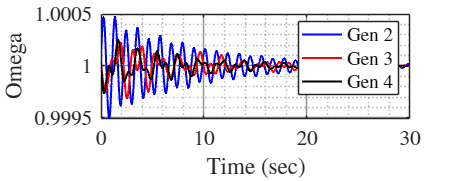

mplot(time_data, w_data, 'Omega')

## Type 2

% t = sym('t', [1 3]);
% w = sym('w', [1 3]);
% Eq = sym('Eq', [1 3]);
% Ed = sym('Ed', [1 3]);
% Efd = sym('Efd', [1 3]);
% Pm = sym('Pm', [1 3]);
% Vref = sym('Vref', [1 3]);
% Pc = sym('Pc', [1 3]);
% Vw = sym('Vw');
% Vc = sym('Vc');
% 
% vars = [t, w, Eq, Ed, Efd, Pm, Vref, Pc, Vw, Vc];
% F = type2(t, w, Eq, Ed, Efd, Pm, Vref, Pc, Vw, Vc, P_gen, Y_gen, E_g, V, T);
% 
% x0 = [0.685 0.614 0.504  1 1 1  0.935 0.991 0.916  0.549 0.537 0.559  1.845 1.935 1.813  7.013 7.204 7.013 1.019 1.040 1.019 7.013 7.204 7.013 1 1];
% sol = vpasolve(F,vars,x0)
% 
% state_vars = [t, w, Eq, Ed, Efd, Pm];
% 
% % making Jacobian
% for i = 1:length(state_vars)
%     for j = 1:3
%         J(i,j) = diff(F(i),t(j));
%         J(i,j+3) = diff(F(i),w(j));
%         J(i,j+6) = diff(F(i),Eq(j));
%         J(i,j+9) = diff(F(i),Ed(j));
%         J(i,j+12) = diff(F(i),Efd(j));
%         J(i,j+15) = diff(F(i),Pm(j));
%     end
%     sol_val{i} = sol.(char(state_vars(i)));
% end
% 
% % substituting solution
% J_val = subs(J, state_vars, sol_val);
% J_val = double(J_val);
% 
% % eigen value and vectors
% [r_ev, eig_val] = eig(J_val);
% l_ev = inv(r_ev);
% 
% % participation factor
% norm_p = []; 
% for i = 1: length(state_vars)
%     p_mat = r_ev(:,i)*l_ev(i,:);
%     diag_vec = abs(diag(p_mat));
%     norm_p = [norm_p diag_vec./max(diag_vec)];
% end
% 
% % calculating mode frequency
% eigen_frequency_mode= abs(imag(diag(eig_val)))/2/pi;